##  Normalized Trajectories 

Author: Michel Barbeau, Carleton University

Version: February 23, 2019

This is a companion Live Script to the paper "Tuning the Demodulation Frequency Based on a Normalized Trajectory Model for Slow Speed Underwater Acoustic Communications".

### Example normalization

In the Cartesian plane, let point $p$ be the coordinate pair $\left(-3535\ldotp 5,3535\ldotp 5\right)$, which corresponds to a distance of $5$ km. Let the velocity vector $\overrightarrow{V}$ be $\left(1,0\right)$, which corresponds to a velocity of $3\ldotp 6$ km/s. The required clockwise rotation for normalization is

$-\theta =-\mathrm{arctan}\left(3535\ldotp 5/-3535\ldotp 5\right)=45$ degrees. 

The corresponding rotation matrix is

$R\left(\theta \right)=\left\lbrack \begin{array}{cc}
\mathrm{cos}\;\theta  & \mathrm{sin}\;\theta \\
-\mathrm{sin}\;\theta  & \mathrm{cos}\;\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 71 & 0\ldotp 71\\
-0\ldotp 71 & 0\ldotp 71
\end{array}\right\rbrack$.

In MATLAB:

clear;
p= [-3535.5 3535.5]; % point
V = [1 0];
R=[0.71 0.71; -0.71 0.71]; % rotation matrix
present(R*p'); % rotation of point

th = 	1.0e+03 *

   -0.0000
    5.0204


present(R*V'); % rotation of velocity vector

th =     0.7100
   -0.7100


Plot of Doppler shift:

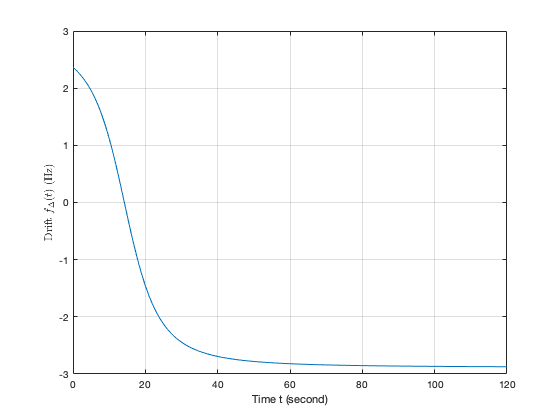

% time points
t=0:120; % seconds
% initial position
p = [0 50]; % meters
% velocity vector
V = (R*[0.5 -2.83]')'; % m/s
% nominal frequency
f0 = 1500; % Hz
% sound speed
c = 1500; % m/s
fs = dopplervstime(p, V, t, f0, c);
figure;
plot(t,fs);
xlabel('Time t (second)');
ylabel('Drift $$f_{\Delta } (t)$$ (Hz)','interpreter','latex');
grid on;

### Example symmetry

Two different trajectories, after 90 degrees rotation for the case on the left, both cases have the same initial position $p$ and symmetrical velocity vectors $\overrightarrow{V}$:

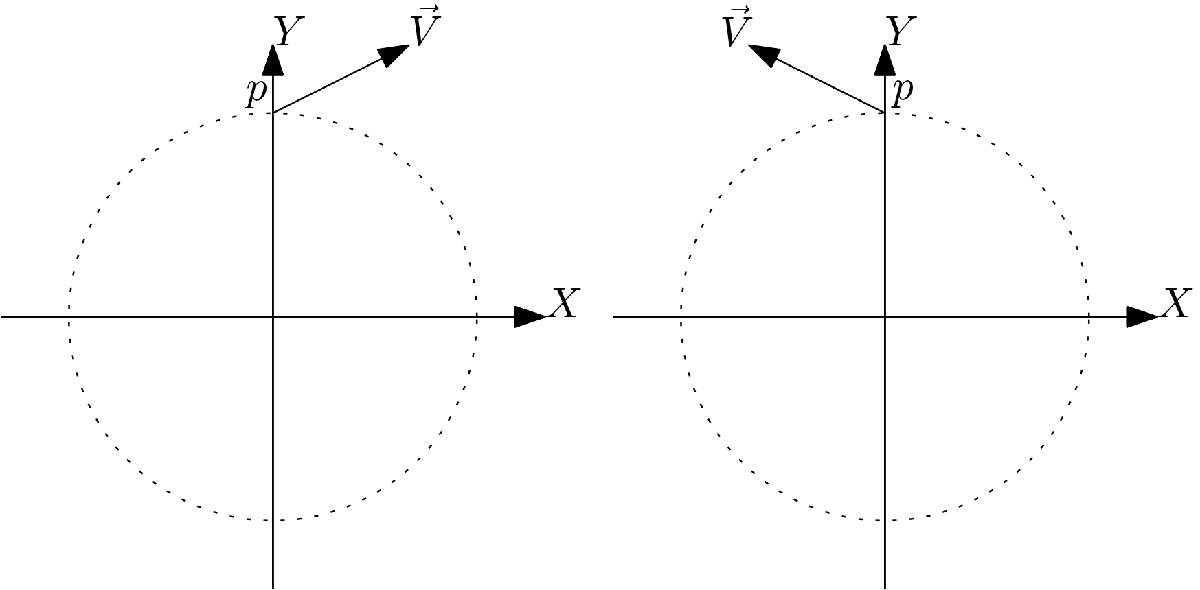

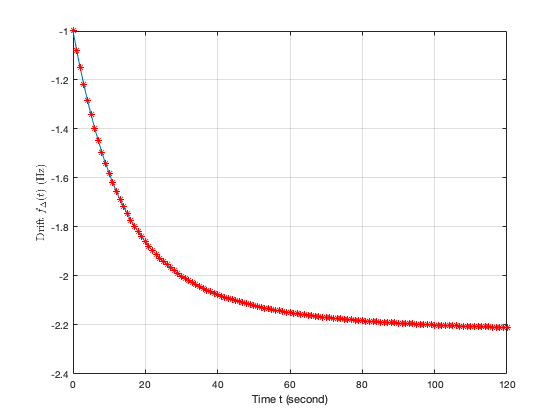

% time points
t=0:120; % seconds
%
%%% left case
%
% rotation matrix, for normalization
R=[0 1; -1 0]; % clockwise 90 degrees
% normalized initial position
p = (R*[-50 0]')'; % meters
% normalized velocity vector
V = (R*[-1 2]')'; % m/s
% nominal frequency
f0 = 1500; % Hz
% sound speed
c = 1500; % m/s
fs  = dopplervstime(p, V, t, f0, c);
figure;
plot(t,fs);
xlabel('Time t (second)');
ylabel('Drift $$f_{\Delta } (t)$$ (Hz)','interpreter','latex');
grid on;
hold on;
% normalized initial position
p = [0 50]; % meters
% normalizd velocity vector
V = [-2 1]; % m/s
% nominal frequency
f0 = 1500; % Hz
% sound speed
c = 1500; % m/s
fs  = dopplervstime(p, V, t, f0, c);
plot(t,fs,'r*');

### Plot of an enumration of normal trajectories

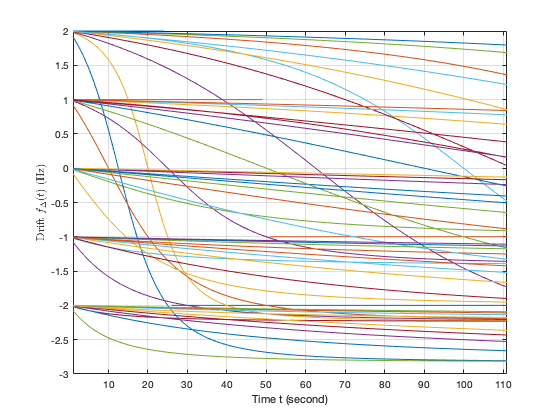

clear;
figure;
% nominal frequency
f0 = 1500; % Hz
t=1:111; % seconds
% sound speed
c = 1500; % m/s
for p2=50:200:850 % initial position loop
    % initial position
    p = [0 p2]; % meters
    for V1=0:1:2 % 1st component of velocity vector loop
            for V2=-2:1:2 % 2nd component of velocity vector loop
                % when velocity vector and y-axis are co-linear, 
                % skip if velocity is positive or vehicle does not cross
                % x-axis
                if ~(V1==0 && V2>=0) && ~(V1==0 && -p2/V2>111) 
                    % velocity vector
                    V = [V1 V2]; % m/s
                    fs  = dopplervstime(p, V, t, f0, c);
                    plot(t,fs);
                    hold on;
                end
            end
    end
end
xlabel('Time t (second)');
ylabel('Drift $$f_{\Delta } (t)$$ (Hz)','interpreter','latex');
grid on;
xlim([1 111]);

### MATLAB implementation of Corollary 2

function fdeltas = dopplervstime(p, V, t, f0, c)
% p = relative initial vehicle positions
% v = relative velocity (m/s)
% t = time points
% f0 = nominal frequency (in Hz)
% c = sound speed (in m/s)
% outputs
    fdeltas = []; % frequency shit vs time
    for i=1:length(t)
        q=t(i)*V+p;
        fdelta = -sign(q(1)*V(1)+q(2)*V(2))*...
            abs(dot(V,q))/sqrt(q(1)^2+q(2)^2)*f0/c;
        fdeltas = [ fdeltas fdelta ];
    end
end